# Behaviour: Elaborated analysis

## 0.1 Load data

data_struct = loadData;
full_subj_list = data_struct.keys;

## 0.2 Select subjects for analysis

%subj_list = full_subj_list(1:10) %random walk; difficult; faces&houses
subj_list = full_subj_list(11:24) %random walk; easy; faces

subj_list = 1×14 cell array
    {'911PoBa'}    {'912ChXi'}    {'913AnLe'}    {'914AmRe'}    {'915YiWa'}    {'916YuWo'}    {'917SaKa'}    {'918KuSh'}    {'919CaMo'}    {'920PoGo'}    {'921ShZh'}    {'922ChOl'}    {'923KiMa'}    {'924PoHa'}


%subj_list = full_subj_list(25:29) %linear; easy
%subj_list = full_subj_list(30:34) %linear; difficult
%subj_list = full_subj_list(35) %ME doing difficult linear

%add nice things to path
addpath('~/Documents/software/cbrewer') %for color
[cb] = cbrewer('qual','Set1',10,'pchip');
addpath('~/Documents/software/raincloud_plots') %for rainclouds
addpath('~/Documents/software/mseb'); %for nice shaded errors
lineProps.width=1; lineProps.col = {cb(1,:), cb(4,:)};
linePropsDiff.width=1; linePropsDiff.col = {'k'}; linePropsDiff.style = '-';


## 1. Mean reaction times and confidence for the four conditions

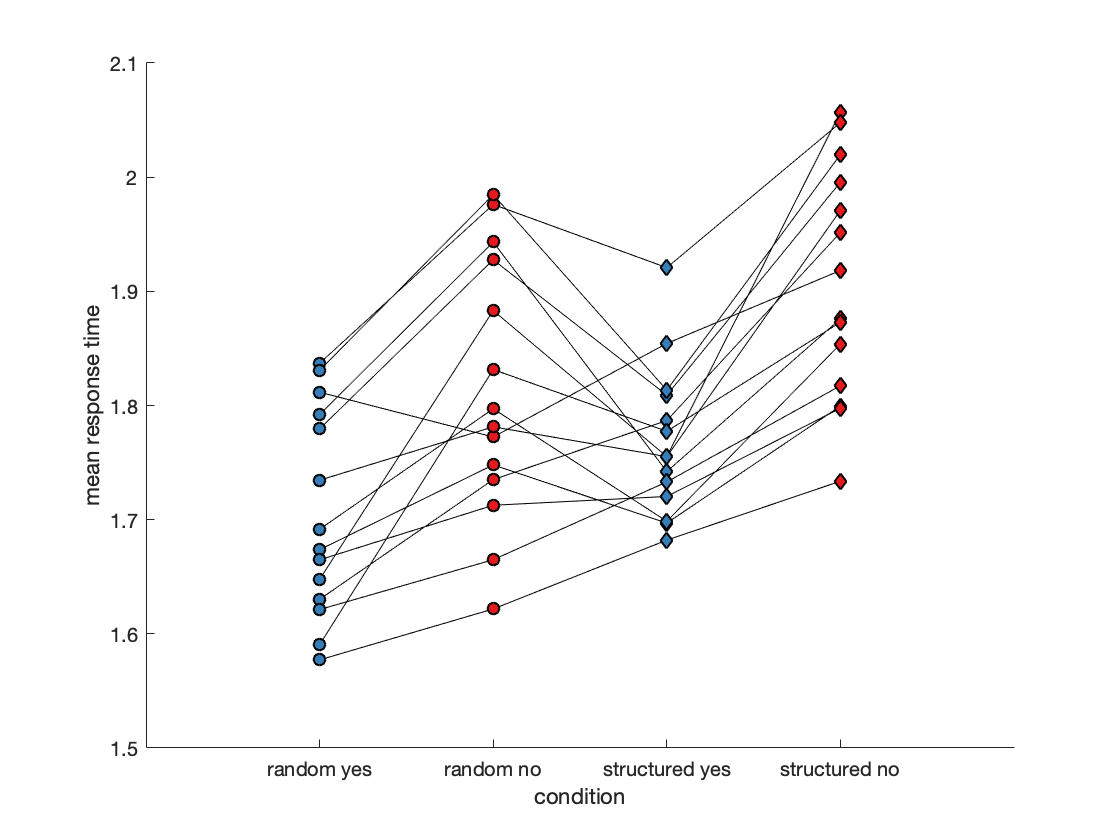

meanRT_rand_yes = [];
meanRT_rand_no = [];
meanRT_struct_yes = [];
meanRT_struct_no = [];
meanRT_correct = [];
meanRT_incorrect = [];
meanConf_rand_yes = [];
meanConf_rand_no = [];
meanConf_struct_yes = [];
meanConf_struct_no = [];

for s = 1:length(subj_list)
    
    subject = data_struct(subj_list{s});
    
    RT_rand_yes = subject.RandomRT(subject.RandomResp==1);
    RT_rand_no = subject.RandomRT(subject.RandomResp==0);
    RT_struct_yes = subject.StructRT(subject.StructResp==1);
    RT_struct_no = subject.StructRT(subject.StructResp==0);
    
    meanRT_rand_yes(s) = nanmean(RT_rand_yes);
    meanRT_rand_no(s) = nanmean(RT_rand_no);
    meanRT_struct_yes(s) = nanmean(RT_struct_yes);
    meanRT_struct_no(s) = nanmean(RT_struct_no);
    
    RT_correct = [subject.RandomRT(subject.RandomCorrect ==1); ...
        subject.StructRT(subject.StructCorrect ==1)];
    RT_incorrect = [subject.RandomRT(subject.RandomCorrect ==0); ...
        subject.StructRT(subject.StructCorrect ==0)];
    
    meanRT_correct(s) = nanmean(RT_correct);
    meanRT_incorrect(s) = nanmean(RT_incorrect);
    
    conf_rand_yes = subject.RandomConf(subject.RandomResp==1);
    conf_rand_no = subject.RandomConf(subject.RandomResp==0);
    conf_struct_yes = subject.StructConf(subject.StructResp==1);
    conf_struct_no = subject.StructConf(subject.StructResp==0);
    
    meanConf_rand_yes(s) = nanmean(conf_rand_yes);
    meanConf_rand_no(s) = nanmean(conf_rand_no);
    meanConf_struct_yes(s) = nanmean(conf_struct_yes);
    meanConf_struct_no(s) = nanmean(conf_struct_no);
    
end

figure; hold on;
plot([meanRT_rand_yes;meanRT_rand_no;meanRT_struct_yes;meanRT_struct_no],'k');
scatter(ones(length(subj_list),1),meanRT_rand_yes,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),meanRT_rand_no,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),meanRT_struct_yes,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),meanRT_struct_no,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('mean response time');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanRT','-dpng','-r600');

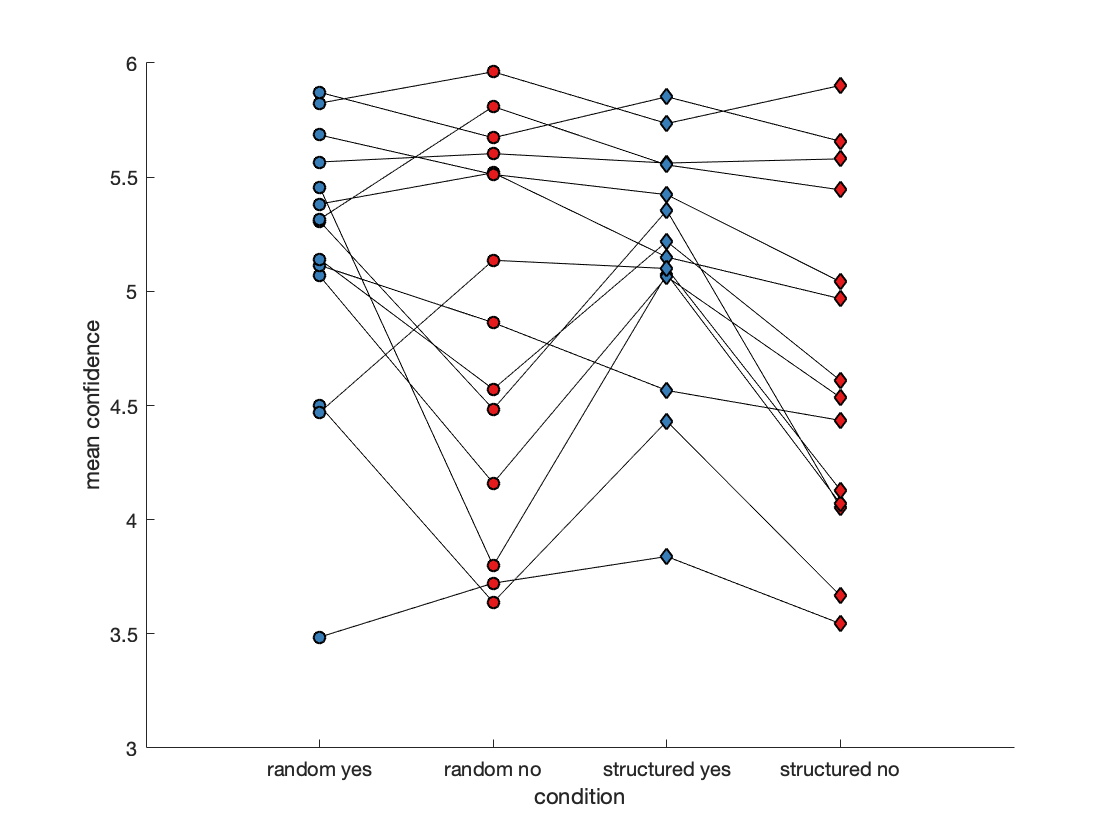


figure; hold on;
plot([meanConf_rand_yes;meanConf_rand_no;meanConf_struct_yes;meanConf_struct_no],'k');
scatter(ones(length(subj_list),1),meanConf_rand_yes,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),meanConf_rand_no,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),meanConf_struct_yes,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),meanConf_struct_no,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('mean confidence');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanConfidence','-dpng','-r600');

## 2. Accuracy

Contrasting mean accuracy and d' for the two tasks.

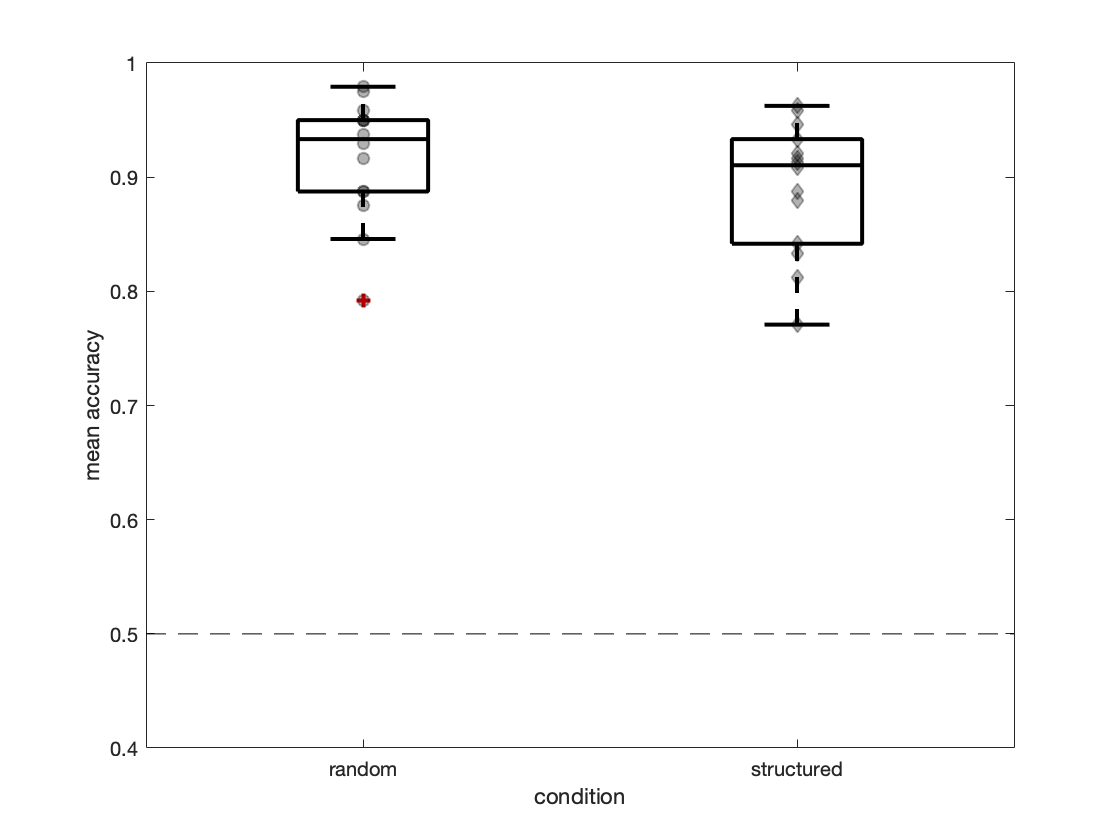

meanAccRand = [];
meanAccStruct = [];
mean_dprimeRand = [];
mean_dprimeStruct = [];
meanAUROCRand = [];
meanAUROCStruct = [];

for s = 1:length(subj_list)
    
    subject = data_struct(subj_list{s});
    
    AccRand = subject.RandomCorrect;
    AccStruct = subject.StructCorrect;
    
    dprimeRand = norminv(nanmean(subject.RandomResp(subject.RandomSignal == 1))) - ...
        norminv(nanmean(subject.RandomResp(subject.RandomSignal == 0)));
    
    dprimeStruct = norminv(nanmean(subject.StructResp(subject.StructSignal == 1))) - ...
        norminv(nanmean(subject.StructResp(subject.StructSignal == 0)));
    
    AUROCRand = extractAUROC(subject.RandomSignal,subject.RandomResp,subject.RandomConf);
    
    AUROCStruct = extractAUROC(subject.StructSignal,subject.StructResp,subject.StructConf);
    
    meanAccRand(s) = nanmean(AccRand);
    meanAccStruct(s) = nanmean(AccStruct);
    
    mean_dprimeRand(s) = dprimeRand;
    mean_dprimeStruct(s) = dprimeStruct;
    
    meanAUROCRand(s) = AUROCRand;
    meanAUROCStruct(s) = AUROCStruct;
    
end
noise1 = normrnd(0,0.05,1,35);
noise2 = normrnd(0,0.05,1,35);
figure; hold on;
h=boxplot([meanAccRand;meanAccStruct]','Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(2*ones(length(subj_list),1)',meanAccStruct,[],'d','MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(ones(length(subj_list),1),meanAccRand,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('mean accuracy');
xlim([0.5,2.5]); xlabel('condition');
ylim([0.4,1]);
plot([0.5,2.5],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanAccuracy','-dpng','-r600');

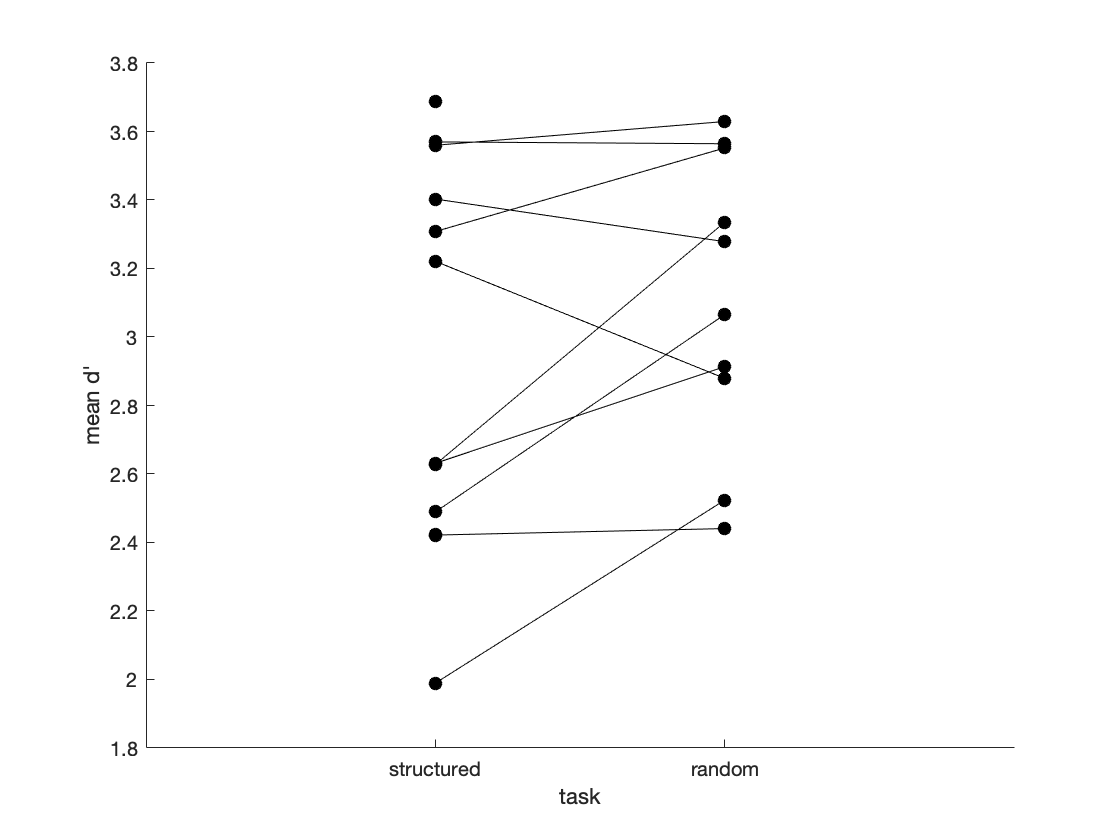

%print('figures/accuracy_300dpi','-dpng','-r300');
figure; hold on;
plot([mean_dprimeStruct;mean_dprimeRand],'k');
scatter(ones(length(subj_list),1),mean_dprimeStruct,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
scatter(2*ones(length(subj_list),1),mean_dprimeRand,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
ylabel('mean d''');
xlim([0,3]); xlabel('task');
set(gca,'xtick',[1:2],'xticklabel',{'structured','random'})

## 2. Serial correlations


Dis_Coeffs = [];
Det_Coeffs = [];

Dis_corr = [];
Det_corr = [];

for s=1:length(subjects) %run over subjects
    
    subject = data_struct(subjects{s});
    
    DisMat = [];
    DetMat = [];
    
    DisSigMat = [];
    DetSigMat = [];
    
    for i = 1:8 %lags
        
        DisVec = []; %responses for discrimination
        DetVec = []; %responses for detection
        
        DisSig = []; %signal for discrimination
        DetSig = []; %signal for detection
        
        for block = 1:5
            
            if toExclude(s,block)==0
                
                % add 32 responses from each block
                DisVec = [DisVec; subject.DisResp(i+(block-1)*40:i+(block-1)*40+32)];
                DetVec = [DetVec; subject.DetResp(i+(block-1)*40:i+(block-1)*40+32)];
                
                % add the appropriate 32 signals
                DisSig = [DisSig; subject.DisSignal(i+(block-1)*40:i+(block-1)*40+32)];
                DetSig = [DetSig; subject.DetSignal(i+(block-1)*40:i+(block-1)*40+32)];
                
            end
        end
        
        DisMat = [DisMat DisVec]; % each lag value gets one column in the matrix
        DetMat = [DetMat DetVec];
        
        DisSigMat = [DisSigMat DisSig]; % same for signals
        DetSigMat = [DetSigMat DetSig];
        
    end
    
    toPredictDis = DisMat(:,8); % what I want to predict is the last column in the response matrix
    toPredictDis(toPredictDis==0)=2; %the second category is used as reference by mnrfit
    regressorsDis = [DisMat(:,7:-1:1), DisSigMat(:,8)]; % responses in reverse lag order, then signals
    Dis_B = mnrfit(regressorsDis, toPredictDis); %fit a logistic regression model
    
    toPredictDet = DetMat(:,8);
    toPredictDet(toPredictDet==0)=2; %the second category is used as reference by mnrfit
    regressorsDet = [DetMat(:,7:-1:1), DetSigMat(:,8)]; % responses in reverse lag order, then signals
    Det_B = mnrfit(regressorsDet, toPredictDet); %fit a logistic regression model
    
    Dis_Coeffs = [Dis_Coeffs Dis_B(2:8)]; % add the first 7 slope betas
    Det_Coeffs = [Det_Coeffs Det_B(2:8)]; % add the first 7 slope betas
    
    Dis_corr = cat(3, Dis_corr, corr(DisMat(~any(isnan(DisMat),2),:))); %compute correlations
    Det_corr = cat(3, Det_corr,corr(DetMat(~any(isnan(DetMat),2),:)));  %compute correlations
    
end

Dis_corr_vec = squeeze(Dis_corr(5:-1:1,6,:))';
Det_corr_vec = squeeze(Det_corr(5:-1:1,6,:))';

figure
hold on
mseb(1:5, [mean(Dis_corr_vec);mean(Det_corr_vec)] ,...
    [std(Dis_corr_vec); std(Det_corr_vec)]/sqrt(length(subjects))*2, lineProps);
legend('discrimination','detection')
plot([1,5],[0,0],'--k');
xlabel('lag');
ylabel('correlation')

figure
hold on
mseb(1:7, [mean(Dis_Coeffs');mean(Det_Coeffs')] ,...
    [std(Dis_Coeffs'); std(Det_Coeffs')]/sqrt(length(subjects)), lineProps);
legend('discrimination','detection')
plot([1,7],[0,0],'--k');
xlabel('lag');
ylabel('weight')
% check overall difference in dependency temporal window:
Dis_window = [];
Det_window = [];
Dis_height = [];
Det_height = [];
for s = 1:length(subjects)
    Dis_window(s) = find([Dis_Coeffs(:,s); 0]<=0,1);
    Det_window(s) = find([Det_Coeffs(:,s); 0]<=0,1);
    Dis_height(s) = mean(Dis_Coeffs(1:Dis_window(s)-1,s));
    Det_height(s) = mean(Det_Coeffs(1:Dis_window(s)-1,s));
    
end

## 3.1 Alternating and sustained effects of previous trials

alternating_regressor = [-1 1 -1 1 -1 1 -1];
sustained_regressor = 3:-1:-3;
predictors = [ones(7,1), alternating_regressor', sustained_regressor'];
trends_dis = [];
trends_det = [];

for i_s = 1:length(subjects);
    trends_dis(:, i_s) = regress(Dis_Coeffs(:,i_s), predictors);
    trends_det(:, i_s) = regress(Det_Coeffs(:,i_s), predictors);
end
%}

## 4. Association between RT and confidence

corr_rand_yes = [];
corr_rand_no = [];
corr_struct_yes = [];
corr_struct_no = [];
%{
RTmat_C = nan(length(subj_list),6);

Undefined function or variable 'subj_list'.

RTmat_A = nan(length(subj_list),6);
RTmat_Y = nan(length(subj_list),6);
RTmat_N = nan(length(subj_list),6);
%}


for s = 1:length(subj_list)
    
    subject = data_struct(subj_list{s});
    
    RT_rand_yes = subject.RandomRT(subject.RandomResp==1);
    RT_rand_no = subject.RandomRT(subject.RandomResp==0);
    RT_struct_yes = subject.StructRT(subject.StructResp==1);
    RT_struct_no = subject.StructRT(subject.StructResp==0);
    
    conf_rand_yes = subject.RandomConf(subject.RandomResp==1);
    conf_rand_no = subject.RandomConf(subject.RandomResp==0);
    conf_struct_yes = subject.StructConf(subject.StructResp==1);
    conf_struct_no = subject.StructConf(subject.StructResp==0);
    
    corr_rand_yes(s) = nancorr(conf_rand_yes, RT_rand_yes);
    corr_rand_no(s) = nancorr(conf_rand_no, RT_rand_no);
    corr_struct_yes(s) = nancorr(conf_struct_yes, RT_struct_yes);
    corr_struct_no(s) = nancorr(conf_struct_no, RT_struct_no);
    
    %{
    for i_r = 1:6
        RTmat_C(s,i_r) = mean(RT_rand_yes(conf_rand_yes==i_r));
        RTmat_A(s,i_r) = mean(RT_rand_no(conf_rand_no==i_r));
        RTmat_Y(s,i_r) = mean(RT_struct_yes(conf_struct_yes==i_r));
        RTmat_N(s,i_r) = mean(RT_struct_no(conf_struct_no==i_r));
    end
    %}
    
end

figure; hold on;
plot([corr_rand_yes;corr_rand_no;corr_struct_yes;corr_struct_no],'k');
scatter(ones(length(subj_list),1),corr_rand_yes,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),corr_rand_no,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),corr_struct_yes,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(5,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),corr_struct_no,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
ylabel('r(confidence, RT)');
xlim([0,5]); xlabel('response');
set(gca,'xtick',[1:4],'xticklabel',{'CC','AC','Y','N'})
plot([0,5],[0,0],'--k');
h = figure; hold on;
set(gcf,'color','w');
confcb = cbrewer('seq','YlOrRd',6);

for i_r = 1:6
    meanRT_rand_yes = [];
    meanRT_rand_no = [];
    meanRT_struct_yes = [];
    meanRT_struct_no = [];
    
    for s = 1:length(subj_list)
        
        subject = data_struct(subj_list{s});
        
        RT_rand_yes = subject.RandomRT(subject.RandomResp==1);
        RT_rand_no = subject.RandomRT(subject.RandomResp==0);
        RT_struct_yes = subject.StructRT(subject.StructResp==1);
        RT_struct_no = subject.StructRT(subject.StructResp==0);
        
        meanRT_rand_yes(s) = nanmean(RT_rand_yes);
        meanRT_rand_no(s) = nanmean(RT_rand_no);
        meanRT_struct_yes(s) = nanmean(RT_struct_yes);
        meanRT_struct_no(s) = nanmean(RT_struct_no);
        
        
    end
    
    
    scatter([(10+i_r-1)*ones(35,1); (20+i_r-1)*ones(35,1); (30+i_r-1)*ones(35,1); (40+i_r-1)*ones(35,1)],...
        [meanRT_rand_yes meanRT_rand_no meanRT_struct_yes, meanRT_struct_no],[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(i_r,:),'LineWidth',1);
    %     scatter((20+i_r-1)*ones(33,1),meanRT_A,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(3,:),'LineWidth',1);
    %     scatter((33+i_r-1)*ones(33,1),meanRT_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(5,:),'LineWidth',1);
    %     scatter((40+i_r-1)*ones(33,1),meanRT_N,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(4,:),'LineWidth',1);
    
    
    %     frame = getframe(h);
    %       im = frame2im(frame);
    %       [imind,cm] = rgb2ind(im,256);
    %       % Write to the GIF File
    %       if i_r == 1
    %           imwrite(imind,cm,'RTbyconf.gif','gif', 'Loopcount',inf);
    %       else
    %           imwrite(imind,cm,'RTbyconf.gif','gif','WriteMode','append');
    %       end
end
ylabel('response time');
xlim([0,50]); xlabel('condition'); ylim([0,1.5]);
title(sprintf('response times by confidence level and condition'));
set(gca,'xtick',[13:10:50],'xticklabel',{'CC','AC','Y','N'})
legend('confidence=1', 'confidence=2','confidence=3','confidence=4','confidence=5','confidence=6',...
    'Location','SouthWest')


view([90 -90])

h = figure; hold on;
set(gcf,'color','w');
confcb = cbrewer('seq','YlOrRd',6);

[meanAcc_struct_yes,meanAcc_A,meanAcc_Y,meanAcc_N] = deal([]);
for i_r = 1:6
    
    for s = 1:length(subjects)
        
        subject = data_struct(subjects{s});
        Acc_struct_yes = subject.StructCorrect(subject.StructResp==1 & subject.StructConf ==i_r);
        Acc_struct_no = subject.StructCorrect(subject.StructResp==0 & subject.StructConf ==i_r);
        Acc_rand_yes = subject.RandomCorrect(subject.RandomResp==1 & subject.RandomConf ==i_r);
        Acc_rand_no = subject.RandomCorrect(subject.RandomResp==0 & subject.RandomConf ==i_r);
        
        if numel(Acc_struct_yes)>5
            meanAcc_C(s,i_r) = nanmean(Acc_struct_yes);
        else
            meanAcc_C(s,i_r) = nan;
        end
        
        if numel(Acc_A)>5
            meanAcc_A(s,i_r) = nanmean(Acc_A);
        else
            meanAcc_A(s,i_r) = nan;
        end
        
        if numel(Acc_Y)>5
            meanAcc_Y(s,i_r) = nanmean(Acc_Y);
        else
            meanAcc_Y(s,i_r) = nan;
        end
        
        if numel(Acc_N)>5
            meanAcc_N(s,i_r) = nanmean(Acc_N);
        else
            meanAcc_N(s,i_r) = nan;
        end
    end
    
    
    scatter([(10+i_r-1)*ones(35,1); (20+i_r-1)*ones(35,1); (30+i_r-1)*ones(35,1); (40+i_r-1)*ones(35,1)],...
        [meanAcc_C(:,i_r); meanAcc_A(:,i_r); meanAcc_Y(:,i_r); meanAcc_N(:,i_r)],[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(i_r,:),'LineWidth',1);
    %     scatter((20+i_r-1)*ones(33,1),meanRT_A,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(3,:),'LineWidth',1);
    %     scatter((33+i_r-1)*ones(33,1),meanRT_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(5,:),'LineWidth',1);
    %     scatter((40+i_r-1)*ones(33,1),meanRT_N,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(4,:),'LineWidth',1);
    
    
    %     frame = getframe(h);
    %       im = frame2im(frame);
    %       [imind,cm] = rgb2ind(im,256);
    %       % Write to the GIF File
    %       if i_r == 1
    %           imwrite(imind,cm,'RTbyconf.gif','gif', 'Loopcount',inf);
    %       else
    %           imwrite(imind,cm,'RTbyconf.gif','gif','WriteMode','append');
    %       end
end
ylabel('accuracy');
xlim([0,50]); xlabel('condition'); ylim([0,1]);
title(sprintf('accuracy by confidence level and condition'));
set(gca,'xtick',[13:10:50],'xticklabel',{'CC','AC','Y','N'})
legend('confidence=1', 'confidence=2','confidence=3','confidence=4','confidence=5','confidence=6',...
    'Location','SouthWest')

view([90 -90])

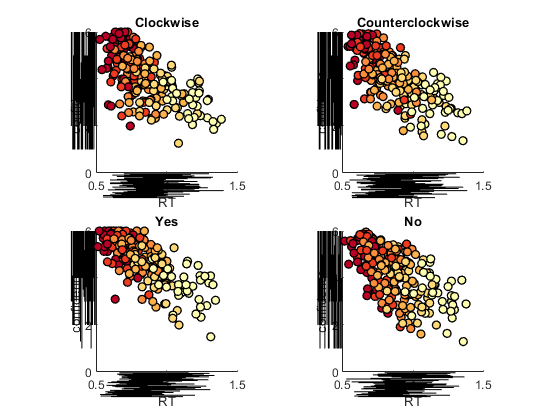

h = figure; hold on;
set(gcf,'color','w');
ax_C = subplot(2,2,1); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('Clockwise');
ylim([0,6]); xlim([0.5,1.5]); ax_C.Clipping = 'off';
ax_A = subplot(2,2,2); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('Counterclockwise');
ylim([0,6]); xlim([0.5,1.5]); ax_A.Clipping = 'off';
ax_Y = subplot(2,2,3); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('Yes');
ylim([0,6]); xlim([0.5,1.5]); ax_Y.Clipping = 'off';
ax_N = subplot(2,2,4); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('No');
ylim([0,6]); xlim([0.5,1.5]); ax_N.Clipping = 'off';

confcb = cbrewer('seq','YlOrRd',6);

[RT_C_hist, RT_A_hist,RT_Y_hist,RT_N_hist,...
    conf_C_hist,conf_A_hist,conf_Y_hist,conf_N_hist] = deal([]);


for s = 1:length(subjects)
    
    subject = data_struct(subjects{s});
    [RT_rand_yes, C_idx] = sort(subject.DisRT(subject.DisResp==1  & included_trials(s,:)'));
    [RT_rand_no, A_idx] = sort(subject.DisRT(subject.DisResp==0  & included_trials(s,:)'));
    [RT_struct_yes, Y_idx] = sort(subject.DetRT(subject.DetResp==1  & included_trials(s,:)'));
    [RT_struct_no, N_idx] = sort(subject.DetRT(subject.DetResp==0  & included_trials(s,:)'));
    
    conf_C = subject.DisConf(subject.DisResp==1  & included_trials(s,:)');
    conf_C = conf_C(C_idx);
    conf_A = subject.DisConf(subject.DisResp==0  & included_trials(s,:)');
    conf_A = conf_A(A_idx);
    conf_Y = subject.DetConf(subject.DetResp==1  & included_trials(s,:)');
    conf_Y = conf_Y(Y_idx);
    conf_N = subject.DetConf(subject.DetResp==0  & included_trials(s,:)');
    conf_N = conf_N(N_idx);
    
    C_bin_size = floor(length(conf_C)/6);
    C_boundaries = [1,C_bin_size*[1:5],length(conf_C)];
    
    A_bin_size = floor(length(conf_A)/6);
    A_boundaries = [1,A_bin_size*[1:5],length(conf_A)];
    
    Y_bin_size = floor(length(conf_Y)/6);
    Y_boundaries = [1,Y_bin_size*[1:5],length(conf_Y)];
    
    N_bin_size = floor(length(conf_N)/6);
    N_boundaries = [1,N_bin_size*[1:5],length(conf_N)];
    
    for i_b = 1:6
        RT_C_hist(s,i_b) = mean(RT_rand_yes(C_boundaries(i_b):C_boundaries(i_b+1)));
        RT_A_hist(s,i_b) = mean(RT_rand_no(A_boundaries(i_b):A_boundaries(i_b+1)));
        RT_Y_hist(s,i_b) = mean(RT_struct_yes(Y_boundaries(i_b):Y_boundaries(i_b+1)));
        RT_N_hist(s,i_b) = mean(RT_struct_no(N_boundaries(i_b):N_boundaries(i_b+1)));
        
        conf_C_hist(s,i_b) = mean(conf_C(C_boundaries(i_b):C_boundaries(i_b+1)));
        conf_A_hist(s,i_b) = mean(conf_A(A_boundaries(i_b):A_boundaries(i_b+1)));
        conf_Y_hist(s,i_b) = mean(conf_Y(Y_boundaries(i_b):Y_boundaries(i_b+1)));
        conf_N_hist(s,i_b) = mean(conf_N(N_boundaries(i_b):N_boundaries(i_b+1)));
        
        scatter(RT_C_hist(s,i_b), conf_C_hist(s,i_b),...
            [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
            'Parent',ax_C);
        
        scatter(RT_A_hist(s,i_b), conf_A_hist(s,i_b),...
            [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
            'Parent',ax_A);
        
        scatter(RT_Y_hist(s,i_b), conf_Y_hist(s,i_b),...
            [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
            'Parent',ax_Y);
        
        scatter(RT_N_hist(s,i_b), conf_N_hist(s,i_b),...
            [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
            'Parent',ax_N);
    end
    plot(ax_C, prctile(RT_rand_yes, [10,90]),-0.03*s*[1,1],'-k')
    plot(ax_C,0.5-0.005*s*[1,1], prctile(conf_C, [10,90]),'-k')
    
    plot(ax_A, prctile(RT_rand_no, [10,90]),-0.03*s*[1,1],'-k')
    plot(ax_A,0.5-0.005*s*[1,1], prctile(conf_A, [10,90]),'-k')
    
    plot(ax_Y, prctile(RT_struct_yes, [10,90]),-0.03*s*[1,1],'-k')
    plot(ax_Y,0.5-0.005*s*[1,1], prctile(conf_Y, [10,90]),'-k')
    
    plot(ax_N, prctile(RT_struct_no, [10,90]),-0.03*s*[1,1],'-k')
    plot(ax_N,0.5-0.005*s*[1,1], prctile(conf_N, [10,90]),'-k')
    
end

## 5. confidence

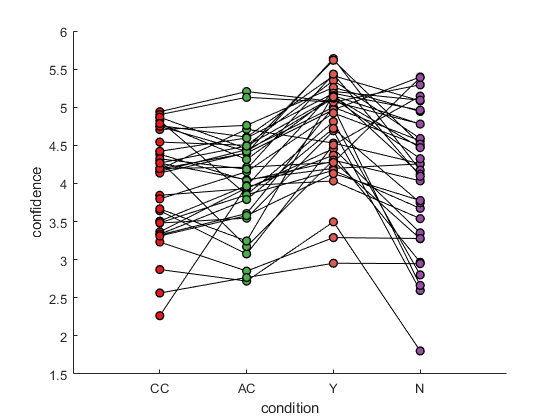

conf_C = [];
conf_A = [];
conf_Y = [];
conf_N = [];

hist_C = [];
hist_A = [];
hist_Y = [];
hist_N = [];

hist_CC = [];
hist_AA = [];
hist_YY = [];
hist_NN = [];

hist_CA = [];
hist_AC = [];
hist_YN = [];
hist_NY = [];

for s = 1:length(subjects)
    
    subject = data_struct(subjects{s});
    
    conf_C(s) = nanmean(subject.DisConf(subject.DisResp==1 & included_trials(s,:)'));
    conf_A(s) = nanmean(subject.DisConf(subject.DisResp==0 & included_trials(s,:)'));
    conf_Y(s) = nanmean(subject.DetConf(subject.DetResp==1 & included_trials(s,:)'));
    conf_N(s) = nanmean(subject.DetConf(subject.DetResp==0 & included_trials(s,:)'));
    
    hist_C(s,:) = hist(subject.DisConf(subject.DisResp==1 & included_trials(s,:)'),1:6);
    hist_A(s,:) = hist(subject.DisConf(subject.DisResp==0 & included_trials(s,:)'),1:6);
    hist_Y(s,:) = hist(subject.DetConf(subject.DetResp==1 & included_trials(s,:)'),1:6);
    hist_N(s,:) = hist(subject.DetConf(subject.DetResp==0 & included_trials(s,:)'),1:6);
    
    
    hist_CC(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_AA(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_YY(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_NN(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    
    hist_CA(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_AC(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_YN(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_NY(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    
end

hist_mat = [mean(hist_C); mean(hist_A); mean(hist_Y); mean(hist_N)];

figure; hold on;
plot([conf_C;conf_A;conf_Y;conf_N],'k');
scatter(ones(35,1),conf_C,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(2*ones(35,1),conf_A,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(3*ones(35,1),conf_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(5,:),'LineWidth',1);
scatter(4*ones(35,1),conf_N,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
ylabel('confidence');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'CC','AC','Y','N'})

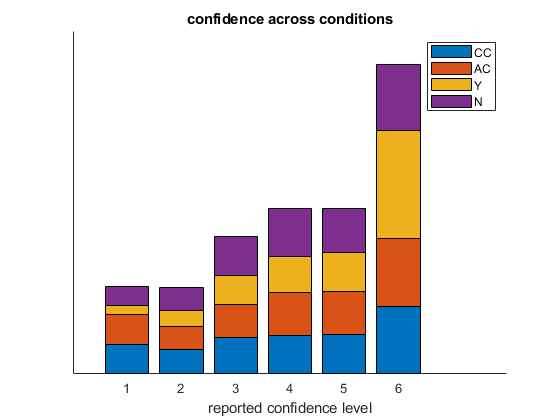

%stacked histogram
figure; hold on;
title('confidence across conditions')
bar(hist_mat','stacked');
colormap(cb([1,3,5,4],:));
xlim([0,8]);set(gca,'xtick',[1:6])
xlabel('reported confidence level'); set(gca, 'ytick',[]);
legend('CC','AC','Y','N')

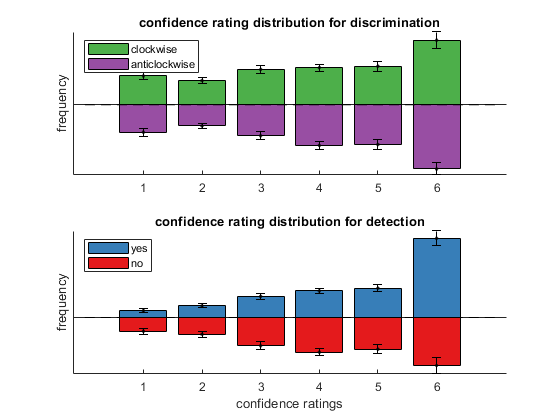


%symmetric bar charts
figure;
subplot(2,1,1);
hold on;
title('confidence rating distribution for discrimination');
c_bar = bar(mean(hist_C),'FaceColor',cb(3,:));
errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
a_bar= bar(-mean(hist_A),'FaceColor',cb(4,:));
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
ylabel('frequency');
errorbar(1:6, -mean(hist_A), std(hist_A)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');
legend([c_bar,a_bar],{'clockwise','anticlockwise'}, 'Location','Northwest')
subplot(2,1,2);
hold on;
title('confidence rating distribution for detection');
y_bar = bar(mean(hist_Y),'FaceColor',cb(2,:));
errorbar(1:6, mean(hist_Y), std(hist_Y)/sqrt(length(subjects)),'.k');
n_bar = bar(-mean(hist_N),'FaceColor',cb(1,:));
errorbar(1:6, -mean(hist_N), std(hist_N)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');
legend([y_bar,n_bar],{'yes','no'}, 'Location','Northwest')

set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');

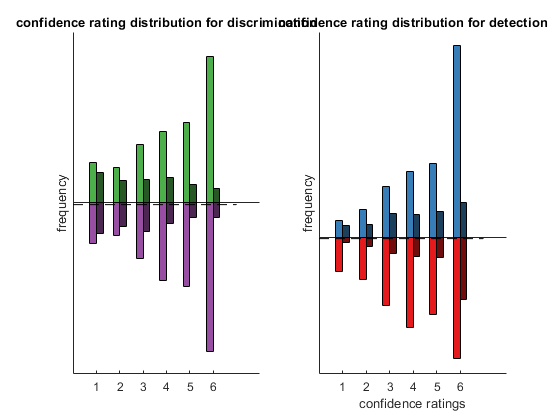


%symmetric bar charts
figure;
subplot(1,2,1);
hold on;
title('confidence rating distribution for discrimination');

c_bar = bar([mean(hist_CC); mean(hist_AC)]','BarWidth',1);
c_bar(1).FaceColor=cb(3,:);
c_bar(2).FaceColor=cb(3,:)/2;

a_bar = bar([-mean(hist_AA); -mean(hist_CA)]','BarWidth',1);
a_bar(1).FaceColor=cb(4,:);
a_bar(2).FaceColor=cb(4,:)/2;

% errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
ylabel('frequency');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');

subplot(1,2,2);
hold on;
title('confidence rating distribution for detection');

y_bar = bar([mean(hist_YY); mean(hist_NY)]','BarWidth',1);
y_bar(1).FaceColor=cb(2,:);
y_bar(2).FaceColor=cb(2,:)/2;

n_bar = bar([-mean(hist_NN); -mean(hist_YN)]','BarWidth',1);
n_bar(1).FaceColor=cb(1,:);
n_bar(2).FaceColor=cb(1,:)/2;

plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');

set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');

fig = gcf;
fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 6.7*0.8 4/3];
print('figures/distributions_byacc','-dpng','-r600');
print('figures/distributions_byacc_300dpi','-dpng','-r300');


sprintf('There is a correlation of %.04f between the attenuation effect and the mean confidence effect',...
    corr(conf_Y'-conf_N',corr_struct_yes'-corr_struct_no'))

## 3. Response Bias

Undefined function or variable 'cor_Y'.

Undefined function or variable 'cor_Y'.

Undefined function or variable 'cor_Y'.

Undefined function or variable 'cor_Y'.

Undefined function or variable 'cor_Y'.

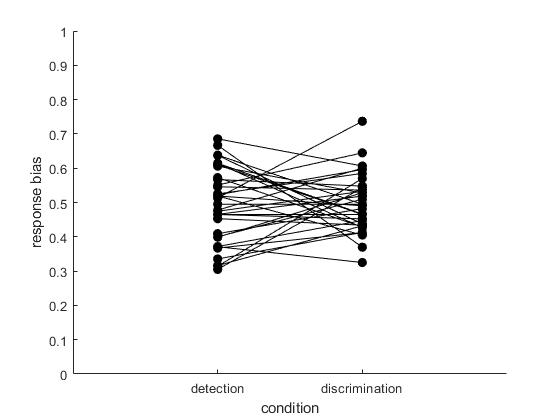

meanRespDet = [];
meanRespDis = [];

for s = 1:length(subjects)
    
    subject = data_struct(subjects{s});
    
    meanRespDet(s) = nanmean(subject.DetResp(included_trials(s,:)'>0));
    meanRespDis(s) = nanmean(subject.DisResp(included_trials(s,:)'>0));
    
end

figure; hold on;
plot([meanRespDet;meanRespDis],'k');
scatter(ones(35,1),meanRespDet,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
scatter(2*ones(35,1),meanRespDis,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
ylabel('response bias'); ylim([0,1])
xlim([0,3]); xlabel('condition');
set(gca,'xtick',[1:2],'xticklabel',{'detection','discrimination'})

## 4. Confidence

For confidence related analyses, we exclude runs in which a particular answer was accompanied by the same confidence rating in 95% of the trials.

I couldn't think of a good way to represent confidence ratings, so I went with a stacked bar plot. 

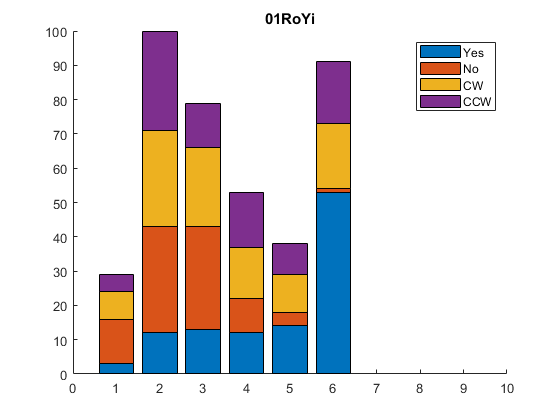

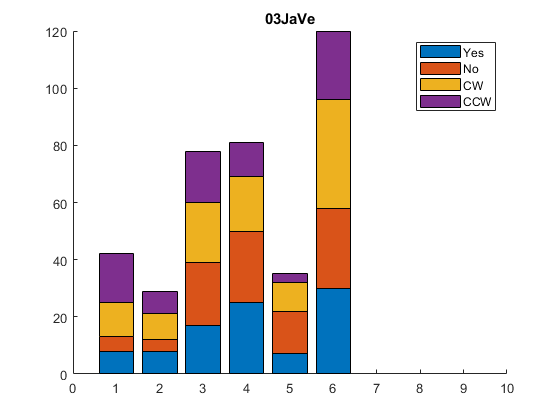

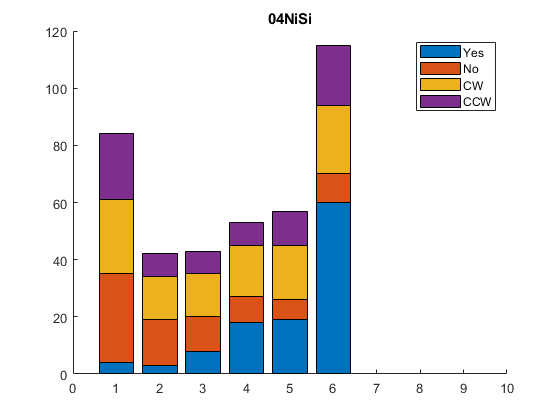

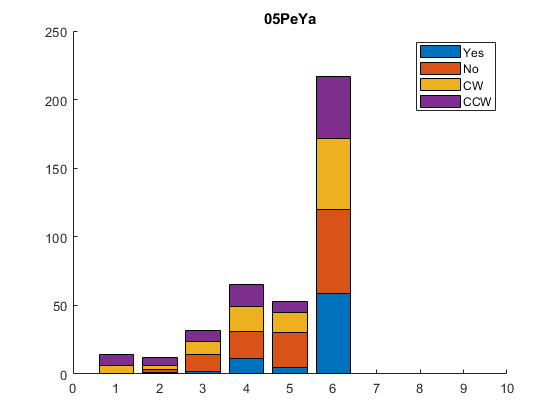

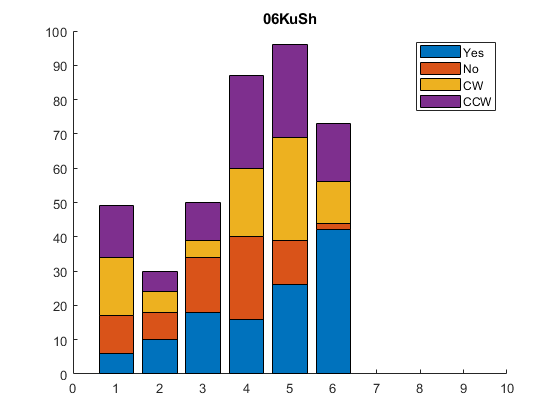

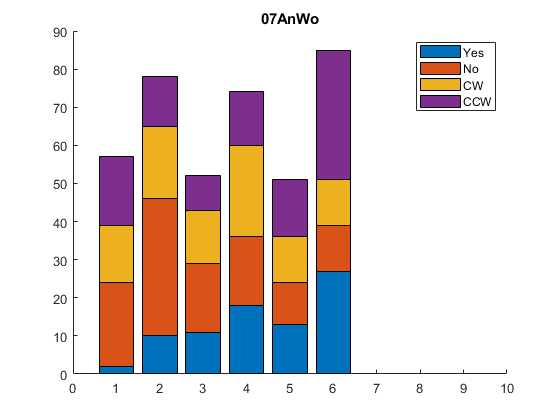

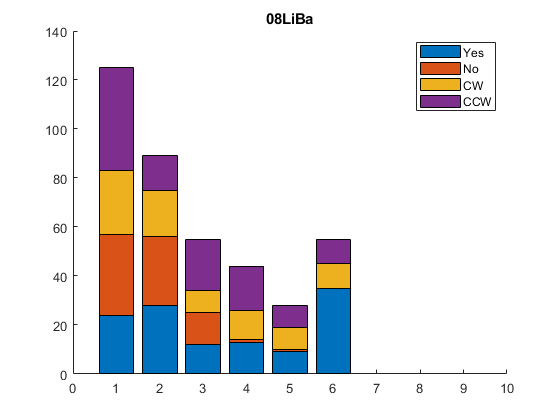

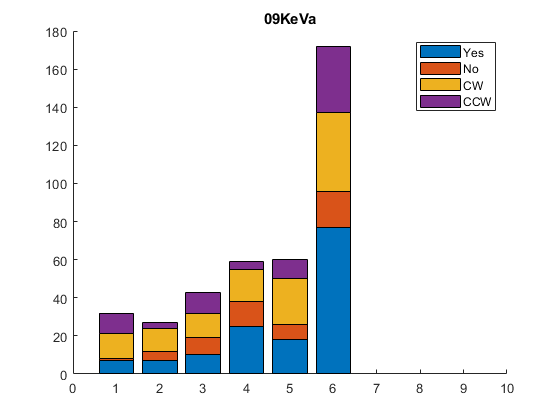

Run 3 of participant 11YaSi was excluded from confidence analysis 



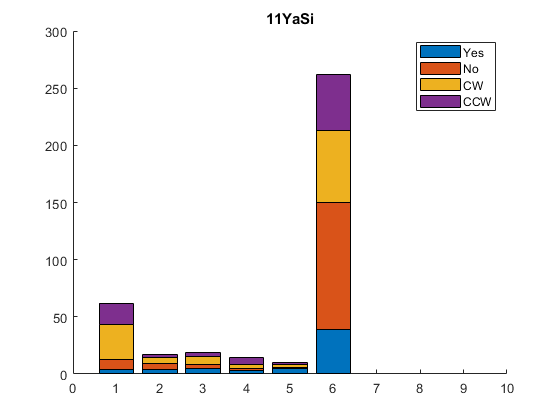

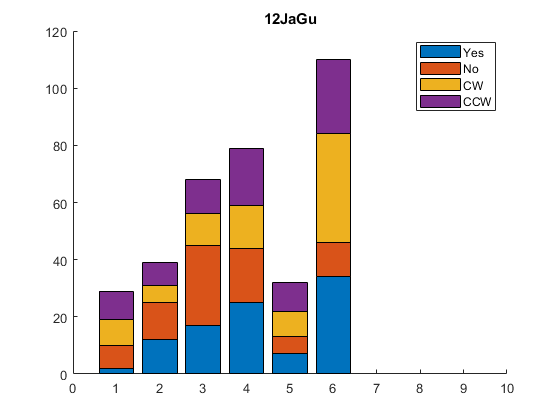

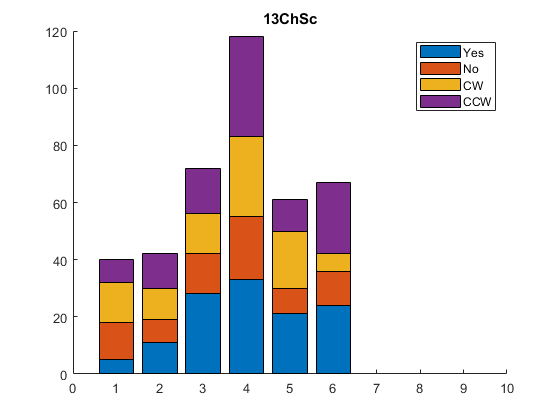

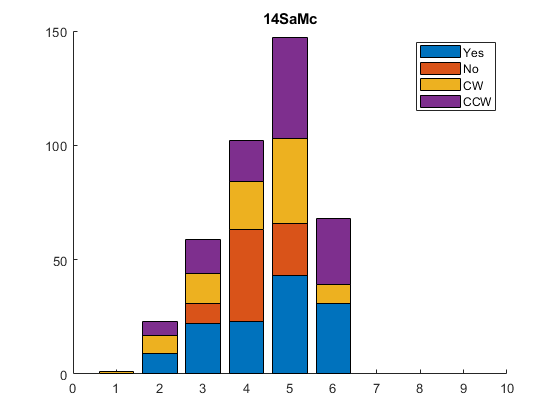

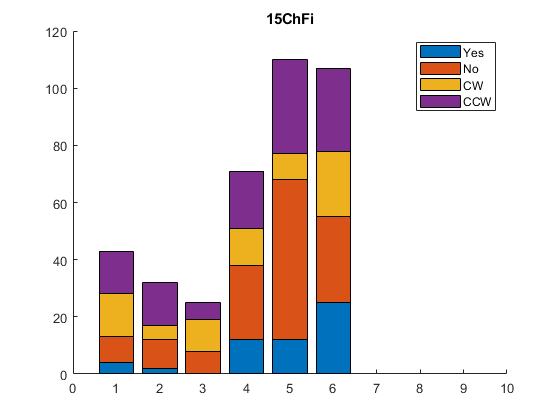

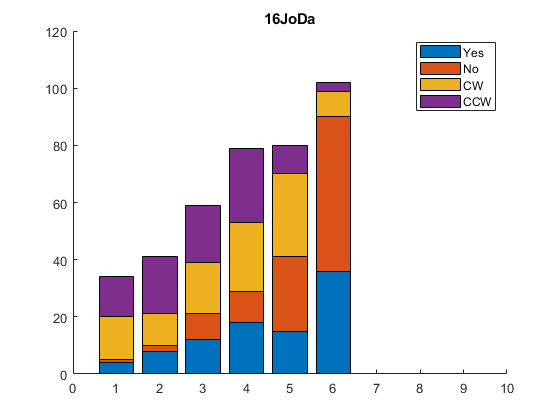

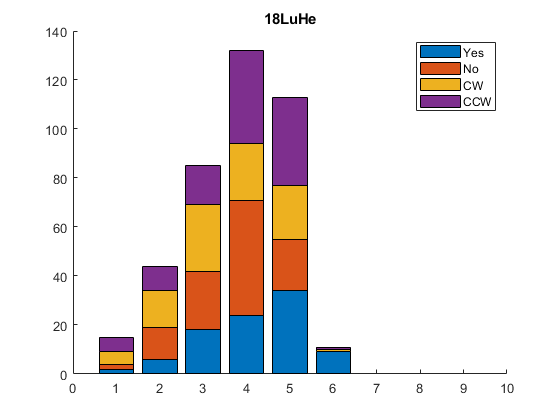

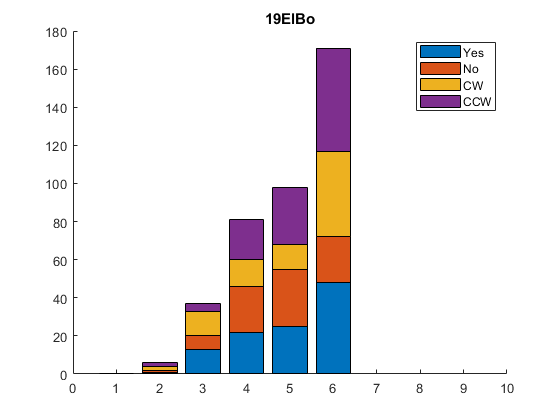

Run 1 of participant 36NaSa was excluded from confidence analysis 



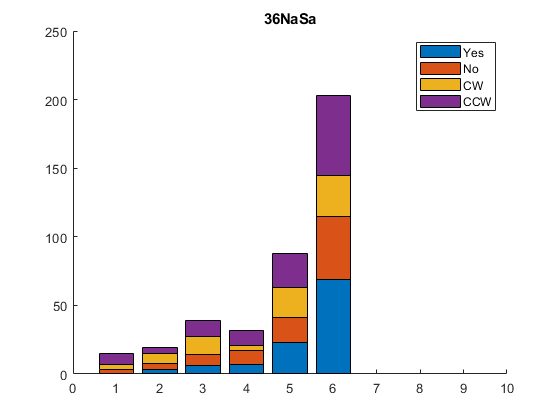

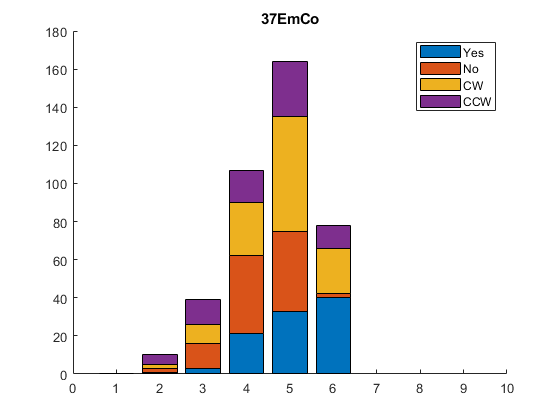

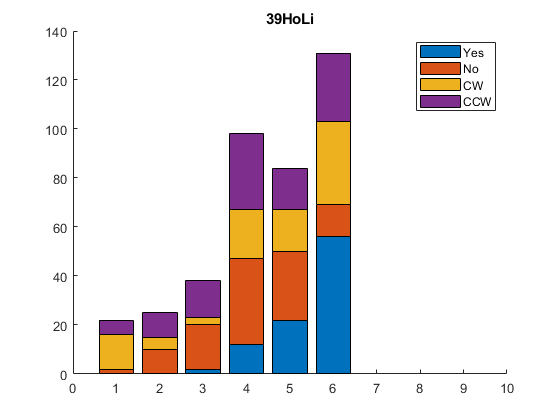

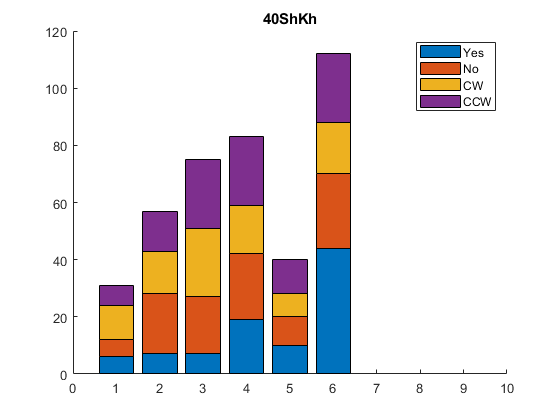

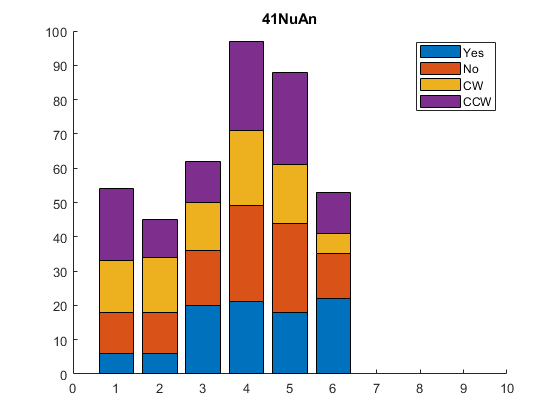

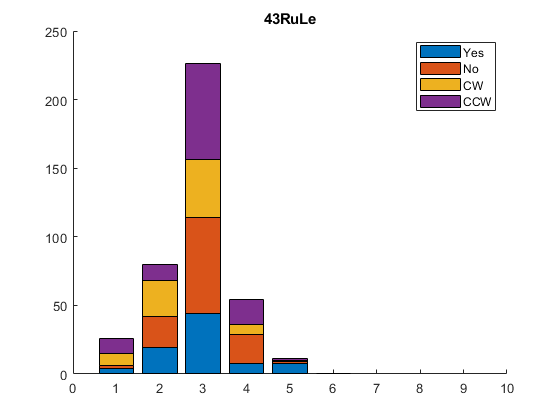

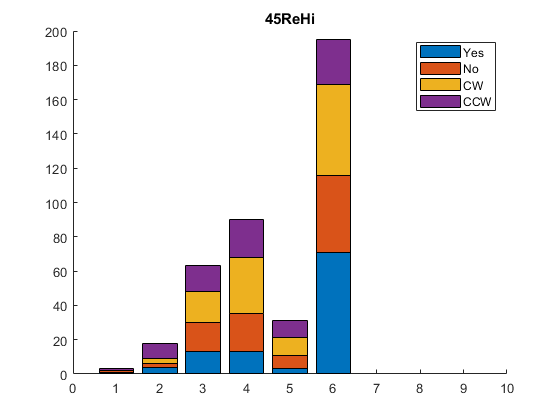

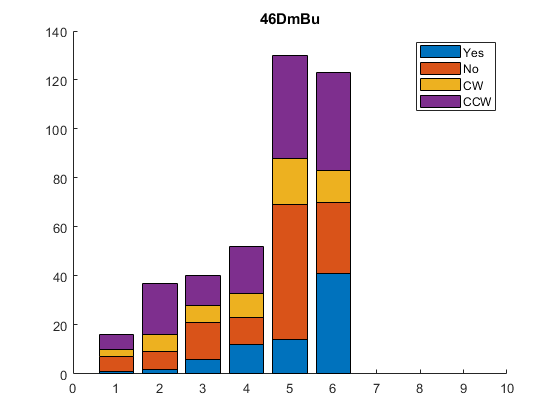

totalConfidenceExclusions = [0,0];

for s = 1:length(subjects)
    
    
    subject = data_struct(subjects{s});
    
    
    for run_num = 1:length(subject.DisRT)/40
        
        %         figure;
        %         title(sprintf('%s: run number %d', subjects{s}, run_num))
        %         hold on;
        range = (run_num-1)*40+1:run_num*40;
        conf_matrix = [hist(subject.DetConf(subject.DetResp(range)==1),1:6);... %yes responses
            hist(subject.DetConf(subject.DetResp(range)==0),1:6);... %no responses
            hist(subject.DisConf(subject.DisResp(range)==1),1:6);... %CW responses
            hist(subject.DisConf(subject.DisResp(range)==0),1:6)];    %CCW responses
        
        %         bar(conf_matrix','stacked');
        %         xlim([0,10]);
        %         legend('Yes','No','CW','CCW')
        
        %check if confidence ratings meet the exclusion criterion
        normalized_conf_matrix = conf_matrix./(repmat(sum(conf_matrix,2),1,6));
        if any(normalized_conf_matrix(:)>0.95) && toExclude(s,run_num)==0
            toExclude(s,run_num)=0.5;
            disp(sprintf('Run %d of participant %s was excluded from confidence analysis \n',run_num, subjects{s}))
            disp(repmat('=',1,60))
            totalConfidenceExclusions(2) = totalConfidenceExclusions(2)+1;
        end
    end
    
    %plot global confidence distribution
    conf_matrix = [hist(subject.DetConf(subject.DetResp==1),1:6);... %yes responses
        hist(subject.DetConf(subject.DetResp==0),1:6);... %no responses
        hist(subject.DisConf(subject.DisResp==1),1:6);... %CW responses
        hist(subject.DisConf(subject.DisResp==0),1:6)];    %CCW responses
    figure;
    hold on
    title(subjects{s})
    bar(conf_matrix','stacked');
    xlim([0,10]);
    legend('Yes','No','CW','CCW')
    
end

## 5. Response Conditional ROCs

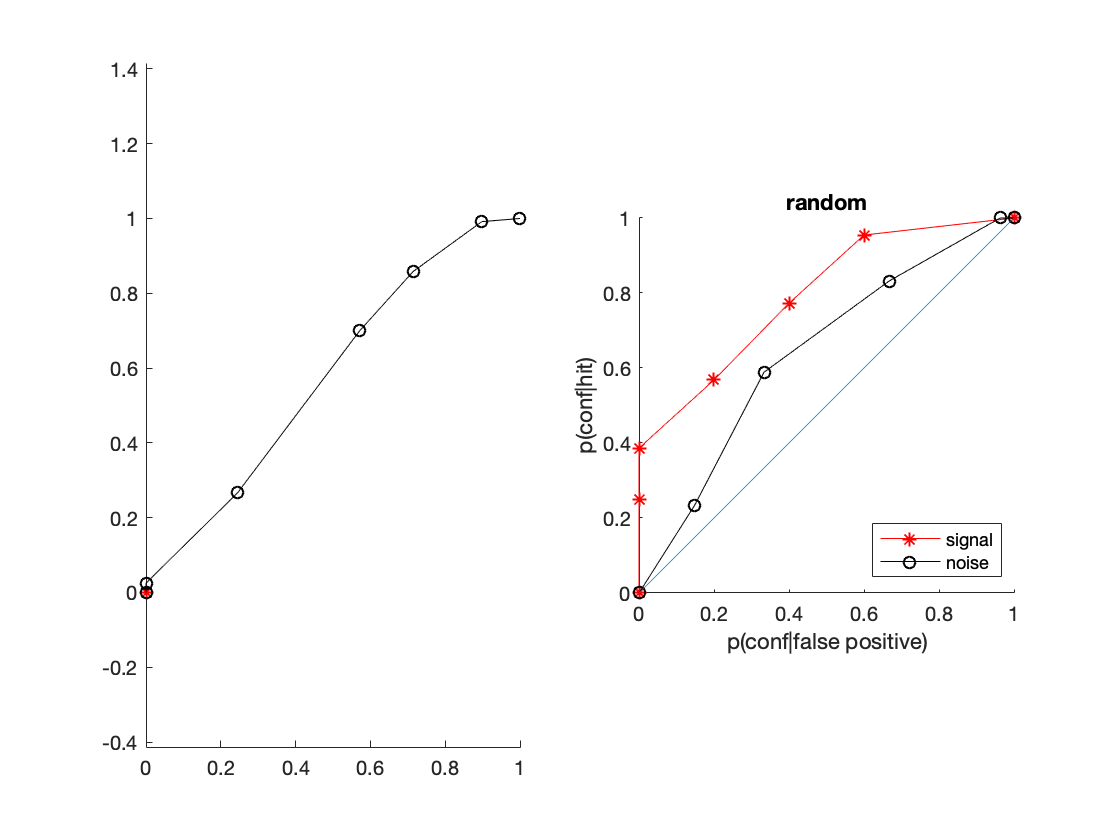

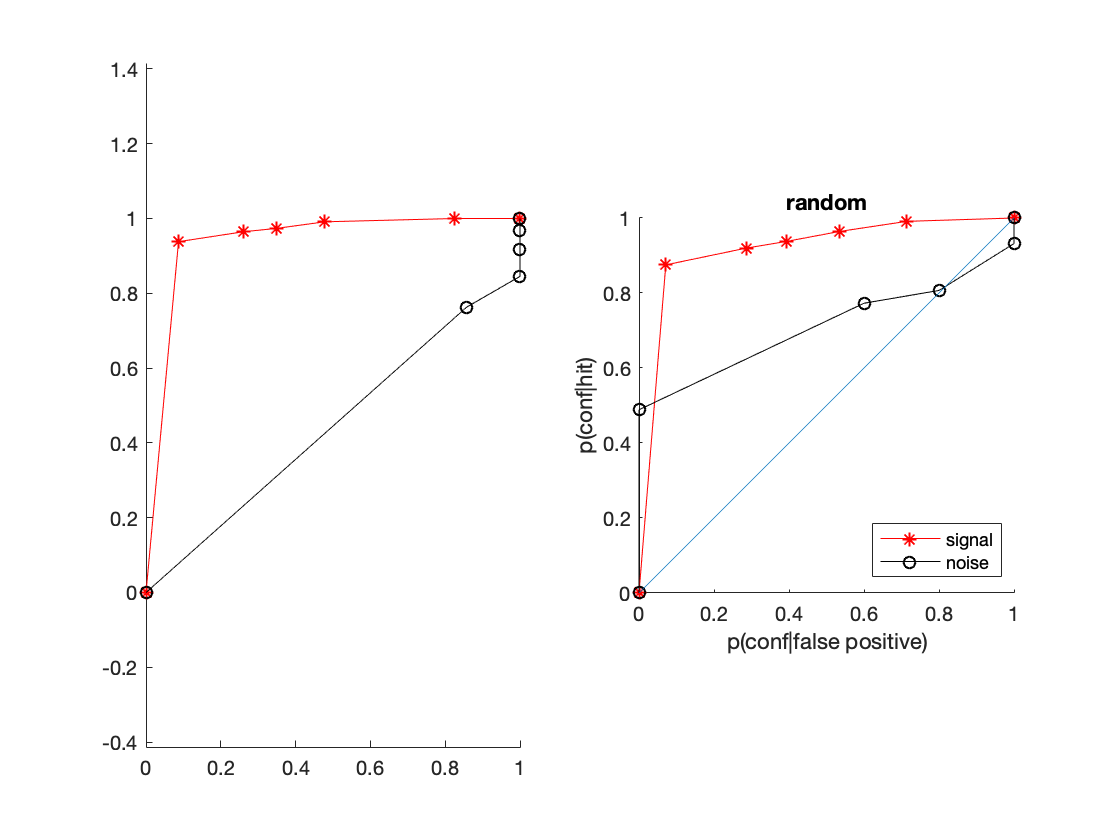

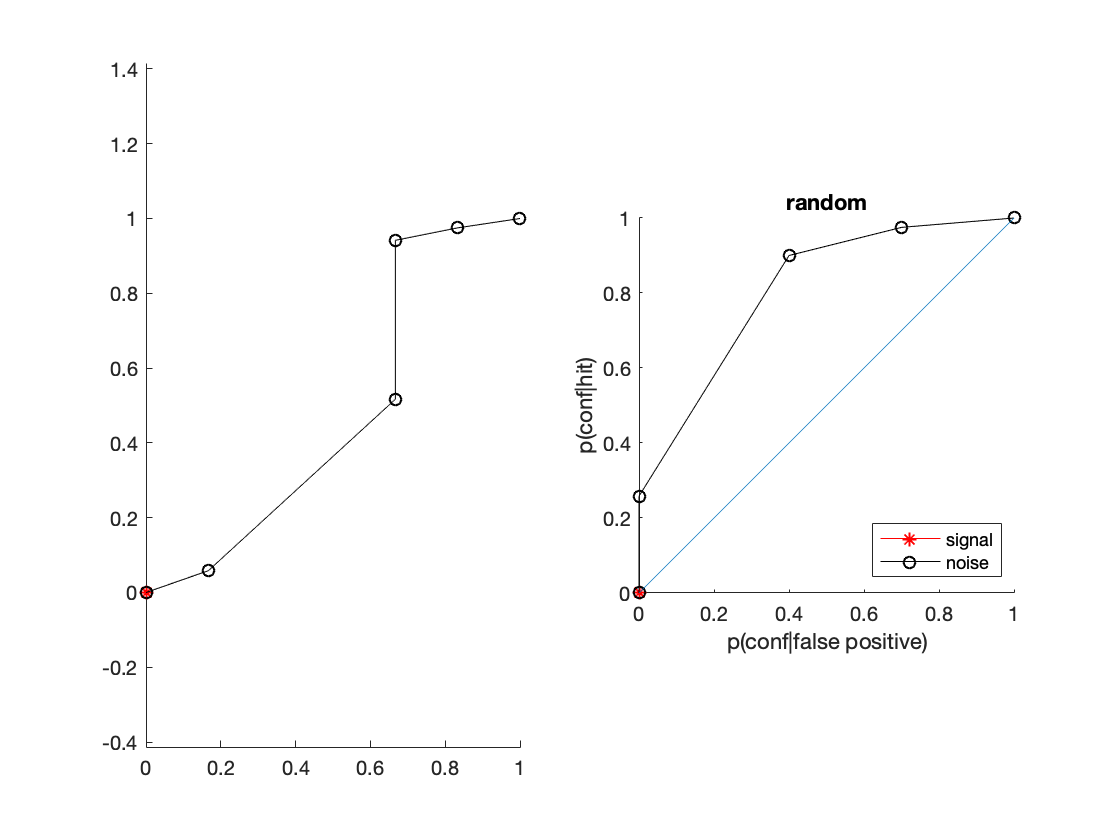

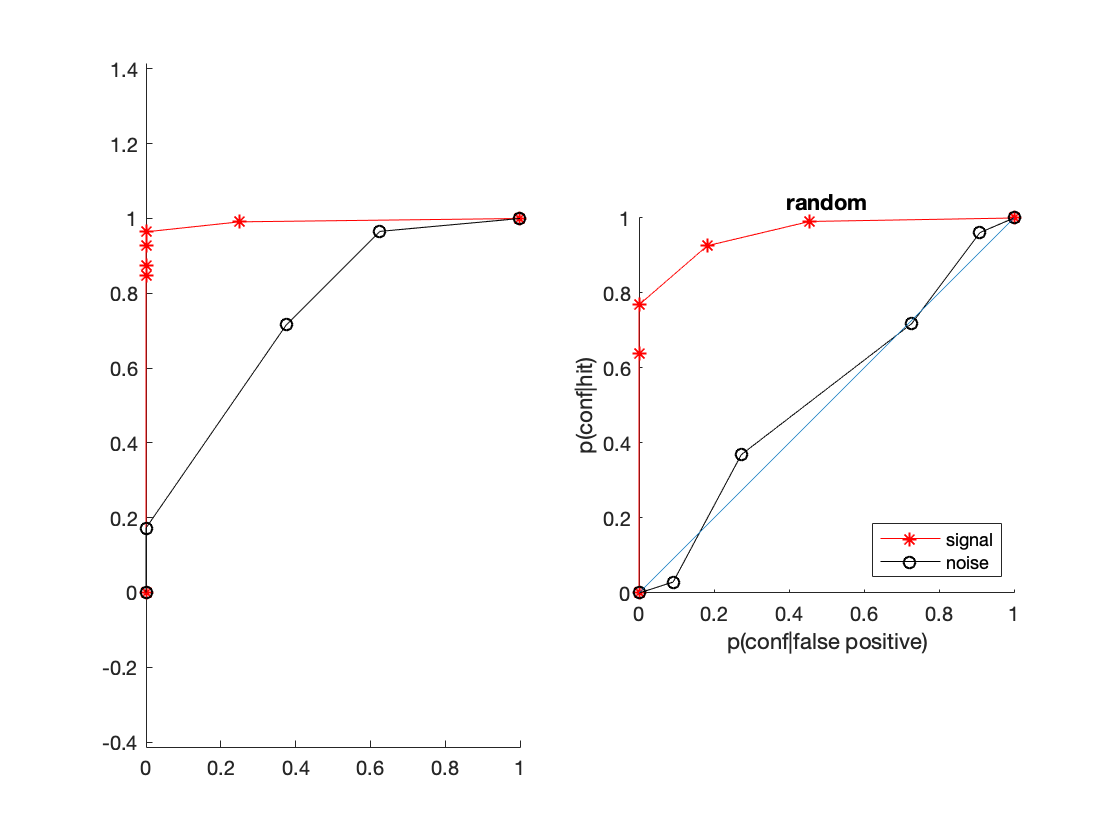

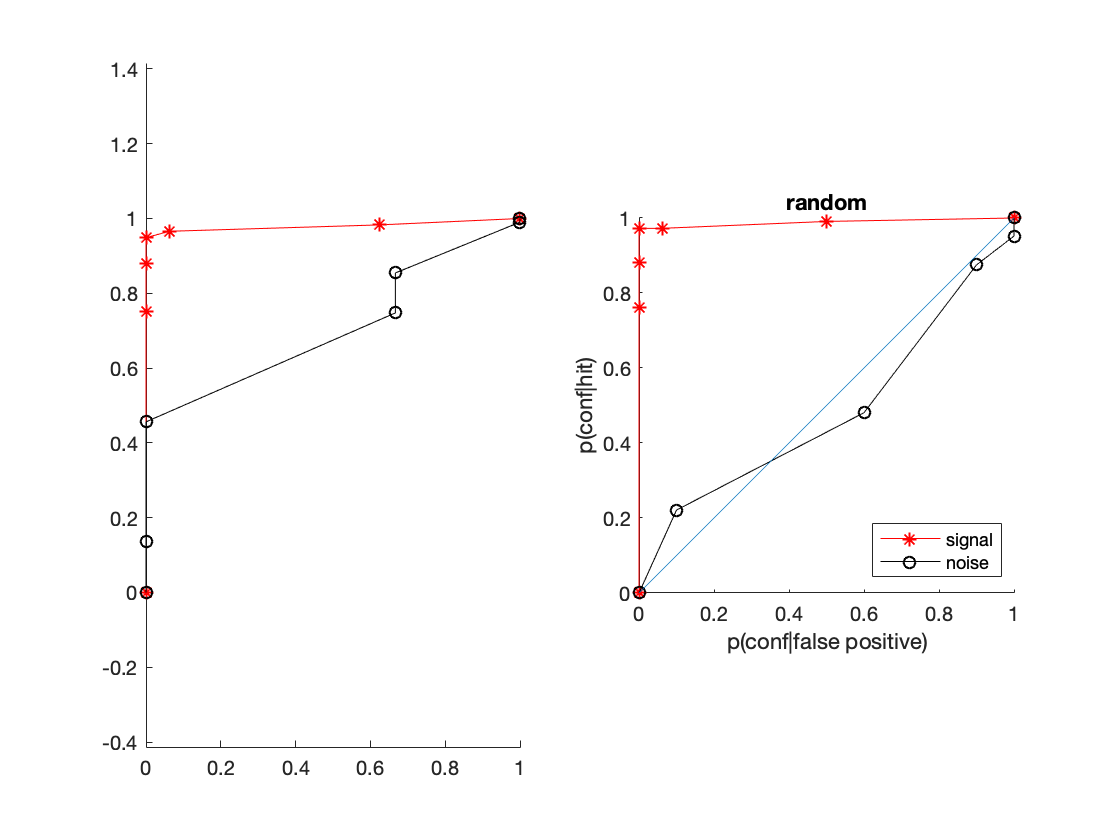

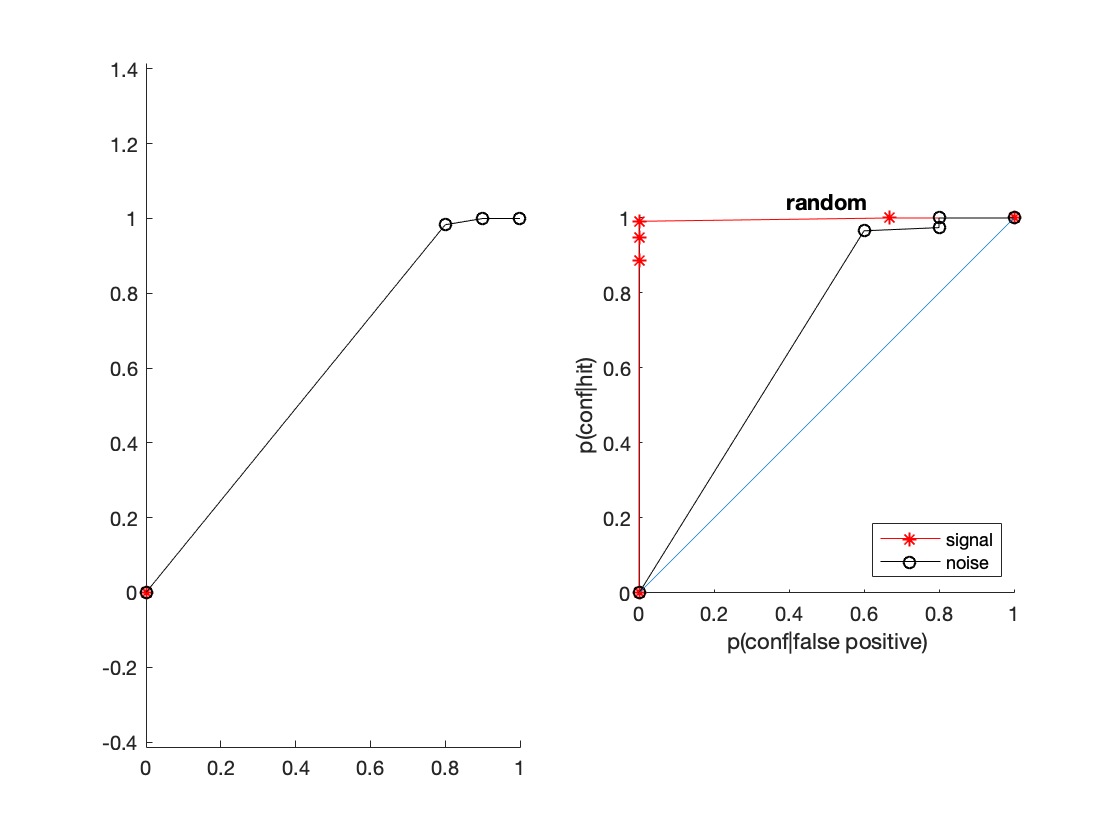

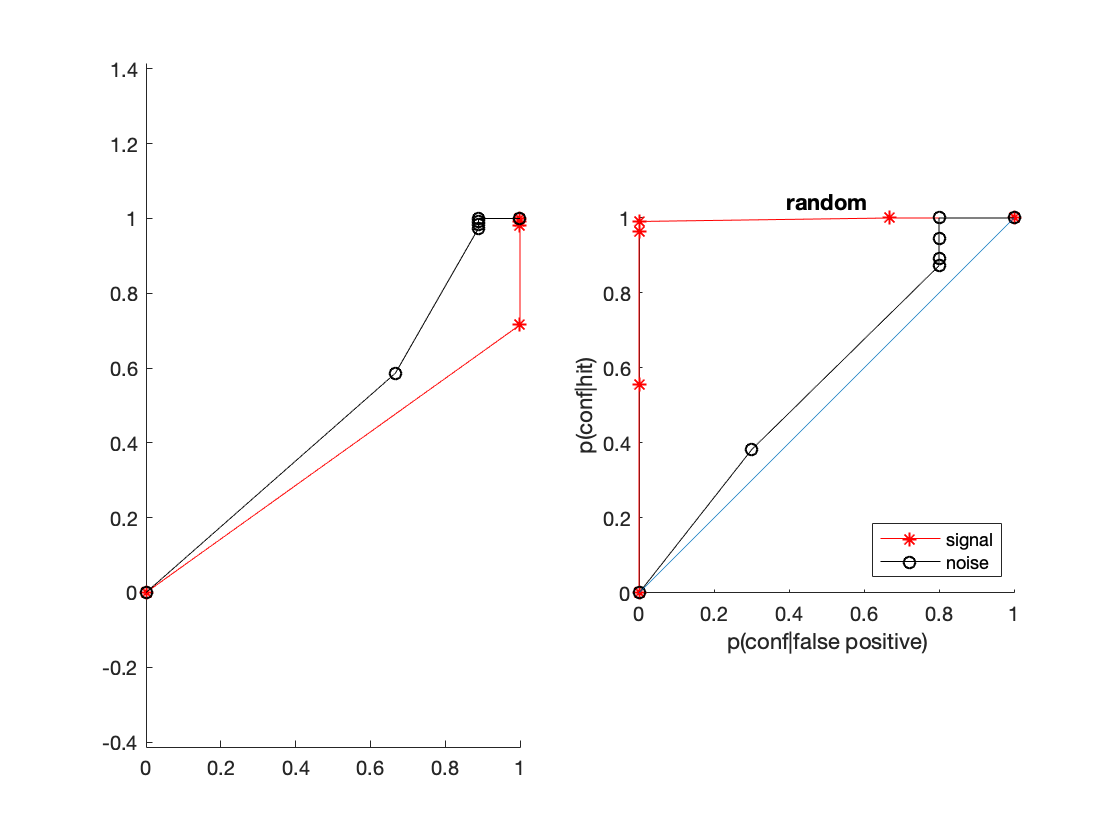

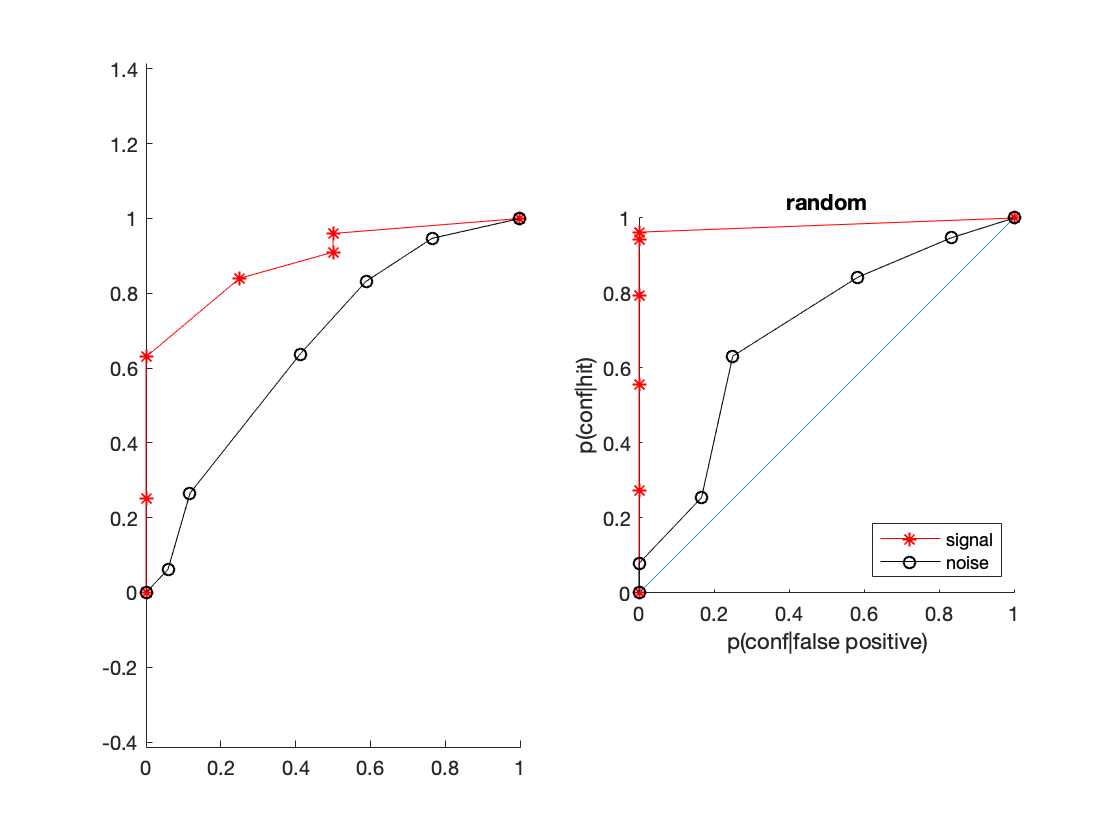

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

[StructSignalYesGroup, StructSignalNoGroup, StructNoiseYesGroup, StructNoiseNoGroup] = deal([]);
[RandSignalYesGroup, RandSignalNoGroup, RandNoiseYesGroup, RandNoiseNoGroup] = deal([]);
[nR_StructSignal,nR_StructNoise,nR_RandSignal,nR_RandNoise] = deal([]);

for s=1:length(subj_list)
    
    subject = data_struct([subj_list{s}]);
    
    
    %break into taskXresponseXsignal
    StructSignalYes = histc(subject.StructConf(subject.StructSignal==1 & subject.StructResp==1),1:6);
    StructSignalNo = histc(subject.StructConf(subject.StructSignal==1 & subject.StructResp==0),1:6);
    StructNoiseYes = histc(subject.StructConf(subject.StructSignal==0 & subject.StructResp==1),1:6);
    StructNoiseNo = histc(subject.StructConf(subject.StructSignal==0 & subject.StructResp==0),1:6);
    
    RandSignalYes = histc(subject.RandomConf(subject.RandomSignal==1 & subject.RandomResp==1),1:6);
    RandSignalNo = histc(subject.RandomConf(subject.RandomSignal==1 & subject.RandomResp==0),1:6);
    RandNoiseYes = histc(subject.RandomConf(subject.RandomSignal==0 & subject.RandomResp==1),1:6);
    RandNoiseNo = histc(subject.RandomConf(subject.RandomSignal==0 & subject.RandomResp==0),1:6);
    
    nR_StructSignal(s,:) = [reshape(StructSignalNo(end:-1:1),1,[]) reshape(StructSignalYes,1,[])];
    nR_StructNoise(s,:) = [reshape(StructNoiseNo(end:-1:1),1,[]) reshape(StructNoiseYes,1,[])];
    nR_RandSignal(s,:) = [reshape(RandSignalNo(end:-1:1),1,[]) reshape(RandSignalYes,1,[])];
    nR_RandNoise(s,:) = [reshape(RandNoiseNo(end:-1:1),1,[]) reshape(RandNoiseYes,1,[])];
    
    
    %% plot random
    %if sum(subject.RandomSignal==0 & subject.RandomResp==1)>1
    figure;
    subplot(1,2,1);
    hold on;
    axis equal
    
    %random yes responses
    plot([0; cumsum(RandNoiseYes(end:-1:1))/sum(RandNoiseYes)],...
        [0; cumsum(RandSignalYes(end:-1:1))/sum(RandSignalYes)], '-*r');
    
    yesAUC(s) = trapz([0; cumsum(RandNoiseYes(end:-1:1))/sum(RandNoiseYes)],...
        [0; cumsum(RandSignalYes(end:-1:1))/sum(RandSignalYes)]);
    
    RandNoiseYesGroup = [RandNoiseYesGroup [0; cumsum(RandNoiseYes(end:-1:1))/sum(RandNoiseYes)]];
    RandSignalYesGroup = [RandSignalYesGroup [0; cumsum(RandSignalYes(end:-1:1))/sum(RandSignalYes)]];
    
    %random no responses
    plot([0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)],...
        [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)],'-ok');
    
    noAUC(s) = trapz([0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)],...
        [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)]);
    
    RandNoiseNoGroup = [RandNoiseNoGroup [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)]];
    RandSignalNoGroup = [RandSignalNoGroup [0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)]];
        
        %% plot structured
    %elseif sum(subject.StructSignal==0 & subject.StructResp==1)>1
    subplot(1,2,2);
    hold on;
    axis equal
    
    %structured yes responses
    plot([0; cumsum(StructNoiseYes(end:-1:1))/sum(StructNoiseYes)],...
        [0; cumsum(StructSignalYes(end:-1:1))/sum(StructSignalYes)], '-*r');
    
    yesAUC(s) = trapz([0; cumsum(StructNoiseYes(end:-1:1))/sum(StructNoiseYes)],...
        [0; cumsum(StructSignalYes(end:-1:1))/sum(StructSignalYes)]);
    
    StructNoiseYesGroup = [StructNoiseYesGroup [0; cumsum(StructNoiseYes(end:-1:1))/sum(StructNoiseYes)]];
    StructSignalYesGroup = [StructSignalYesGroup [0; cumsum(StructSignalYes(end:-1:1))/sum(StructSignalYes)]];
    
    
    %structured no responses
    plot([0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)],...
        [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)],'-ok');
    
    noAUC(s) = trapz([0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)],...
        [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)]);
    
    StructNoiseNoGroup = [StructNoiseNoGroup [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)]];
    StructSignalNoGroup = [StructSignalNoGroup [0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)]];
    
    xlabel('p(conf|false positive)');
    ylabel('p(conf|hit)');
    title('random');
    set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
    set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
    refline(1,0);
    legend('signal', 'noise', 'Location', 'southeast')
    %end
end

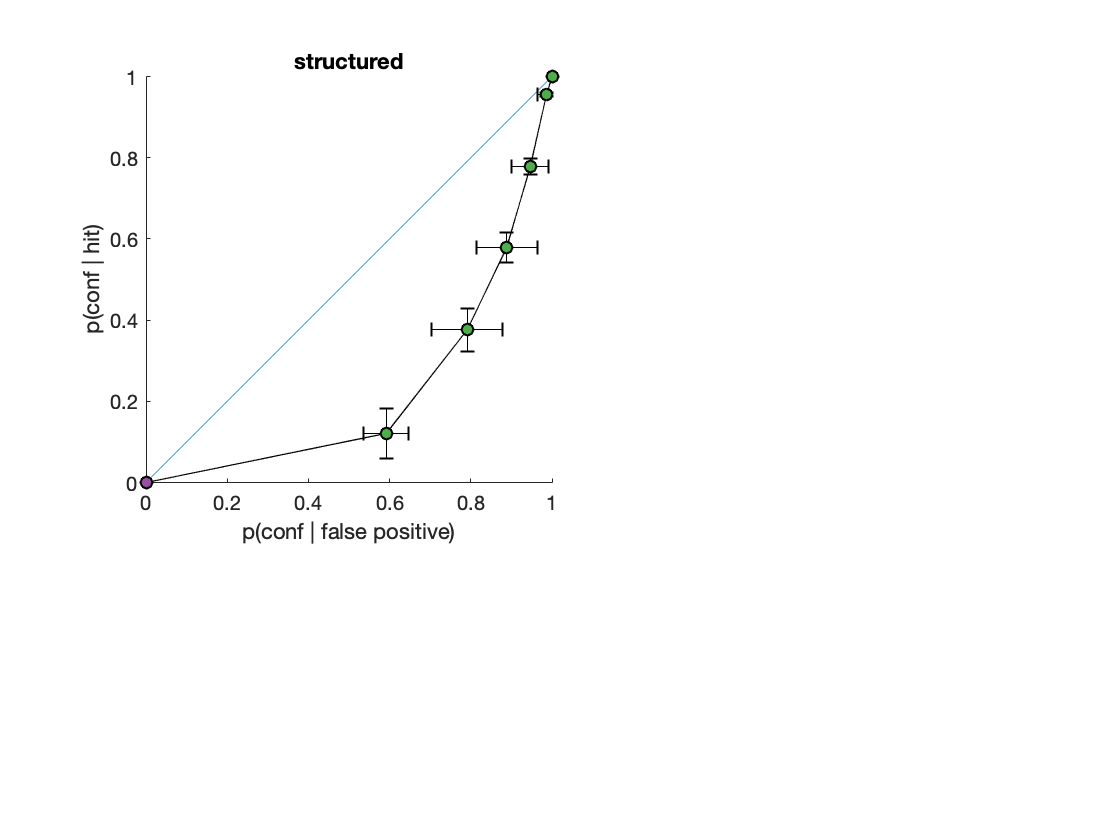

set(0,'defaultAxesFontSize',10)
figure;
ax1=subplot(3,4,[1,2,5,6]);
hold on;
axis equal
%up responses
refline(1,0);

errorbar(mean(StructSignalYesGroup,2),mean(StructSignalNoGroup,2),std(StructSignalYesGroup')/sqrt(length(subj_list)),std(StructSignalYesGroup')/sqrt(length(subj_list)),...
    std(StructSignalNoGroup')/sqrt(length(subj_list)),std(StructSignalNoGroup')/sqrt(length(subj_list)),'k')
c=plot(mean(StructSignalYesGroup,2),mean(StructSignalNoGroup,2), '-ok', 'MarkerFaceColor',cb(3,:));
errorbar(mean(StructNoiseYesGroup,2),mean(StructNoiseNoGroup,2),std(StructNoiseYesGroup')/sqrt(length(subj_list)),std(StructNoiseYesGroup')/sqrt(length(subj_list)),...
    std(StructNoiseNoGroup')/sqrt(length(subj_list)),std(StructNoiseNoGroup')/sqrt(length(subj_list)),'k')
a=plot(mean(StructNoiseYesGroup,2),mean(StructNoiseNoGroup,2), '-ok', 'MarkerFaceColor', cb(4,:));
xlabel('p(conf | false positive)');
ylabel('p(conf | hit)');
title('structured');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);

legend([c,a],{sprintf('clockwise (%.02f)',mean(upAUC)), sprintf('anticlockwise (%.02f)',mean(downAUC))}, 'Location', 'southeast')

Undefined function or variable 'upAUC'.


ax2=subplot(3,4,[3,4,7,8]);
hold on;
axis equal
refline(1,0);
%up responses
errorbar(mean(StructYesGroup,2),mean(RandYesGroup,2),std(StructYesGroup')/sqrt(35),std(StructYesGroup')/sqrt(35),...
    std(RandYesGroup')/sqrt(35),std(RandYesGroup')/sqrt(35),'k')
y=plot(mean(StructYesGroup,2),mean(RandYesGroup,2), '-ok', 'MarkerFaceColor',cb(2,:));
errorbar(mean(RandNoGroup,2),mean(StructNoGroup,2),std(RandNoGroup')/sqrt(35),std(RandNoGroup')/sqrt(35),...
    std(StructNoGroup')/sqrt(35),std(StructNoGroup')/sqrt(35),'k')
n=plot(mean(RandNoGroup,2),mean(StructNoGroup,2), '-ok', 'MarkerFaceColor', cb(1,:));
xlabel('p(conf | false positive)');
ylabel('p(conf | hit)');
title('detection');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([y,n],{sprintf('signal (%.02f)',mean(yesAUC)), sprintf('noise (%.02f)', mean(noAUC))}, 'Location', 'southeast')

ax3=subplot(3,4,[9,10]);
hold on;
c_bar = bar(mean(hist_C),'FaceColor',cb(3,:));
errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
a_bar= bar(-mean(hist_A),'FaceColor',cb(4,:));
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
errorbar(1:6, -mean(hist_A), std(hist_A)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');
ax4=subplot(3,4,[11,12]);
hold on;
y_bar = bar(mean(hist_Y),'FaceColor',cb(2,:));
errorbar(1:6, mean(hist_Y), std(hist_Y)/sqrt(length(subjects)),'.k');
n_bar = bar(-mean(hist_N),'FaceColor',cb(1,:));
errorbar(1:6, -mean(hist_N), std(hist_N)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');
linkaxes([ax3,ax4])
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
fig = gcf;
fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 6.7*0.8 4];
print('figures/rcROC_distributions','-dpng','-r600');
print('figures/rcROC_distributions_300dpi','-dpng','-r300');

## Pattern matching

To check if participants were using a specific phase-locked pattern in their 'no' responses, I compute the correlation of each stimulus with the mean of the clockwise and clockwise pure stimuli. I then look only at trials for which this value is negative, and compute the correlation of this value with the confidenceXresponse vector.

If participants used a pattern matching strategy, this value shoud be positive, whereas if they were looking for phase invariant signal it should be negative. The values are generally negative. 

Interestingly, the participant that shows the strongest pattern matching behaviour is 04NiSi, that shows no detection asymmetry and the strongest phsae-invariant matching is 18LuHe, that shows a very strong one with the noise curve lying beneath the diagonal.

pattern_matching = containers.Map;
for s = 1:length(subjects)
    subject = data_struct(subjects{s});
    pattern_matching(subjects{s}) = corr([subject.DetPatternFit(subject.DetResp==1 & subject.DetPatternFit'<0)';...
        subject.DetPatternFit(subject.DetResp==0 & subject.DetPatternFit'<0)'],...
        [subject.DetConf(subject.DetResp==1 & subject.DetPatternFit'<0);...
        -subject.DetConf(subject.DetResp==0 & subject.DetPatternFit'<0)]);
end